Runge's function

xx = linspace(-1, 1);
yy = 1./(1 + 25 * xx .^ 2);

% figure
% plot(xx, yy, 'm--')
% axis([-1 1 -1 2])
% title('Runge function')

Fit 5 points with not-a-knot cubic spline

x = linspace(-1, 1, 5);
y = 1./(1 + 25 * x .^ 2);

% xx = linspace(-1, 1);
% yycs = spline(x, y, xx);

% figure
% plot(xx, yy, 'm--', 'LineWidth',2)
% hold on
% plot(x, y, 'kO', 'LineWidth',2)
% hold on
% plot(xx, yycs, 'c-', 'LineWidth',2)
% axis([-1 1 -1 2])
% title('Runge function and fit with 5-point cubic line')
% Relative Error
xtest = 0.22

xtest = 0.2200

ytrue = 1./(1 + 25 * xtest .^ 2);

ypred = spline  (x, y, xtest)

ypred = 0.7657


err = abs((ytrue - ypred) / ytrue) * 100

err = 69.2203


% figure
% plot(xx, yy, 'm--', 'LineWidth',2)
% hold on
% plot(x, y, 'kO', 'LineWidth',2)
% hold on
% plot(xx, yycs, 'c-', 'LineWidth',2)
% hold on
% plot(xtest, ypred, 'gO', 'LineWidth',2)
% hold on
% plot(xtest, ytrue, 'bO', 'LineWidth',2)
% axis([-1 1 -1 2])
% title('Runge function and fit with 5-point cubic line(fit predict and true value)')

Fit 6 points with not-a-knot cubic spline

x = linspace(-1, 1, 6);
y = 1./(1 + 25 * x .^ 2);

% xx = linspace(-1, 1);
% yycs = spline(x, y, xx);
% 
% figure
% plot(xx, yy, 'm--', 'LineWidth',2)
% hold on
% plot(x, y, 'kO', 'LineWidth',2)
% hold on
% plot(xx, yycs, 'c-', 'LineWidth',2)
% axis([-1 1 -1 2])
% title('Runge function and fit with 6-point cubic line')
% Relative Error
xtest = 0.22

xtest = 0.2200

ytrue = 1./(1 + 25 * xtest .^ 2);

ypred = spline  (x, y, xtest)

ypred = 0.4856


err = abs((ytrue - ypred) / ytrue) * 100

err = 7.3268

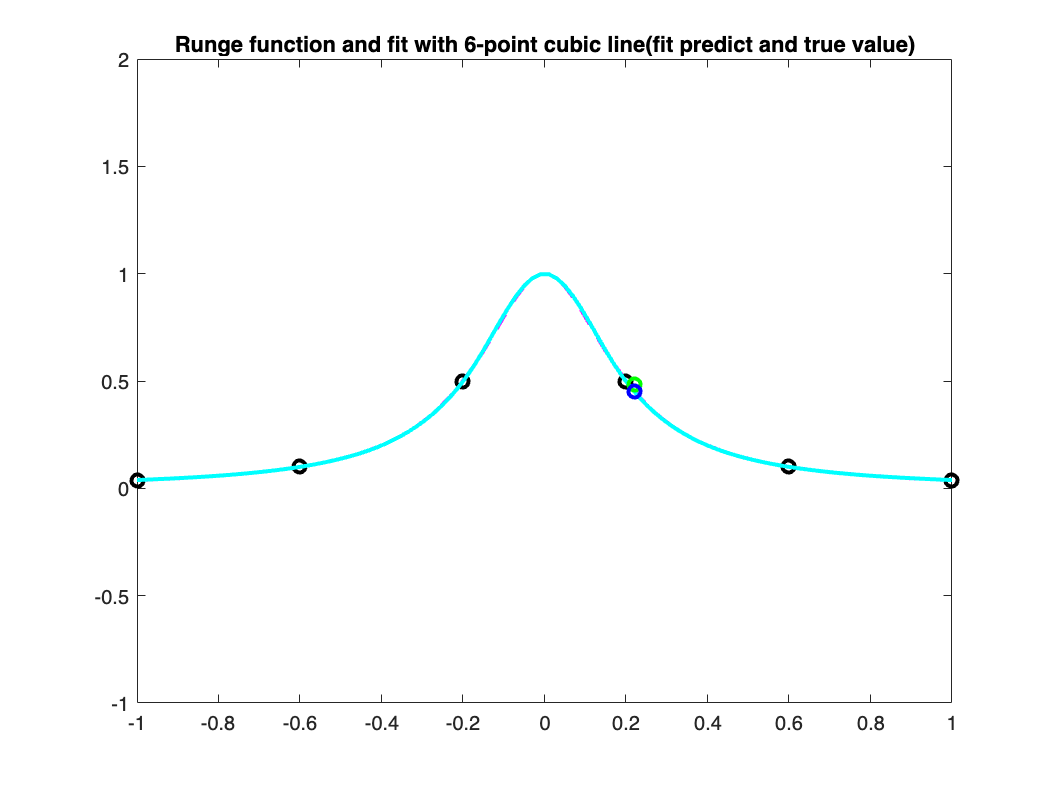


% figure
% plot(xx, yy, 'm--', 'LineWidth',2)
% hold on
% plot(x, y, 'kO', 'LineWidth',2)
% hold on
% plot(xx, yycs, 'c-', 'LineWidth',2)
% hold on
% plot(xtest, ypred, 'gO', 'LineWidth',2)
% hold on
% plot(xtest, ytrue, 'bO', 'LineWidth',2)
% axis([-1 1 -1 2])
% title('Runge function and fit with 6-point cubic line(fit predict and true value)')

Fit n points with not-a-knot cubic spline (easy way)

x = linspace(-1, 1, 13);
y = 1./(1 + 25 * x .^ 2);

xx = linspace(-1, 1);
yycs = spline(x, y, xx);

xtest = 0.22

xtest = 0.2200

ytrue = 1./(1 + 25 * xtest .^ 2);

ypred = spline  (x, y, xtest)

ypred = 0.4506


err = abs((ytrue - ypred) / ytrue) * 100

err = 0.4240

for n = 2:20
    x = linspace(-1, 1, n);
    y = 1./(1 + 25 * x.^2);
    
    ypred = spline(x, y, xtest);
    err_n = abs((ytrue - ypred) / ytrue) * 100;
    
    fprintf('n = %2d, error = %.4f%%\n', n, err_n);
    
    if err_n < 1
        fprintf('Achieved error < 1%% at n = %d\n', n);
        break;
    end
end

n =  2, error = 91.5000%
n =  3, error = 110.7150%
n =  4, error = 37.9725%
n =  5, error = 69.2203%
n =  6, error = 7.3268%
n =  7, error = 25.5876%
n =  8, error = 19.8899%
n =  9, error = 4.5168%
n = 10, error = 15.2446%
n = 11, error = 1.1731%
n = 12, error = 6.8990%
n = 13, error = 0.4240%


Achieved error < 1% at n = 13
